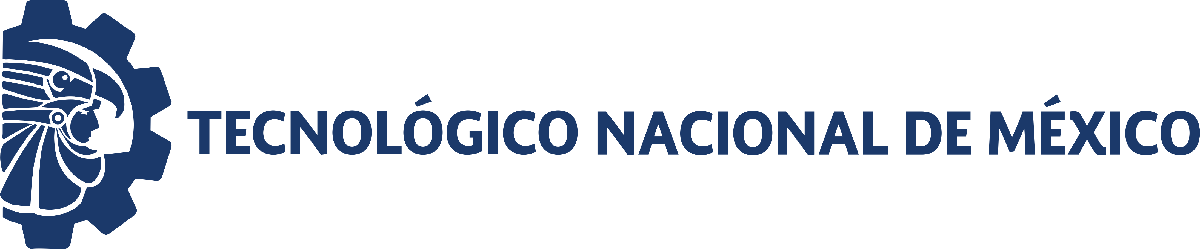                                 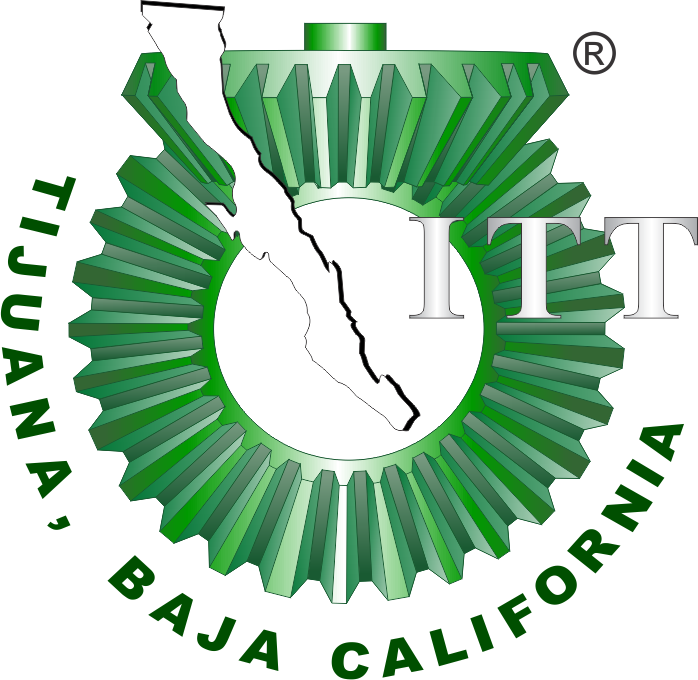

# Práctica cuatro: Sistema endocrino

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

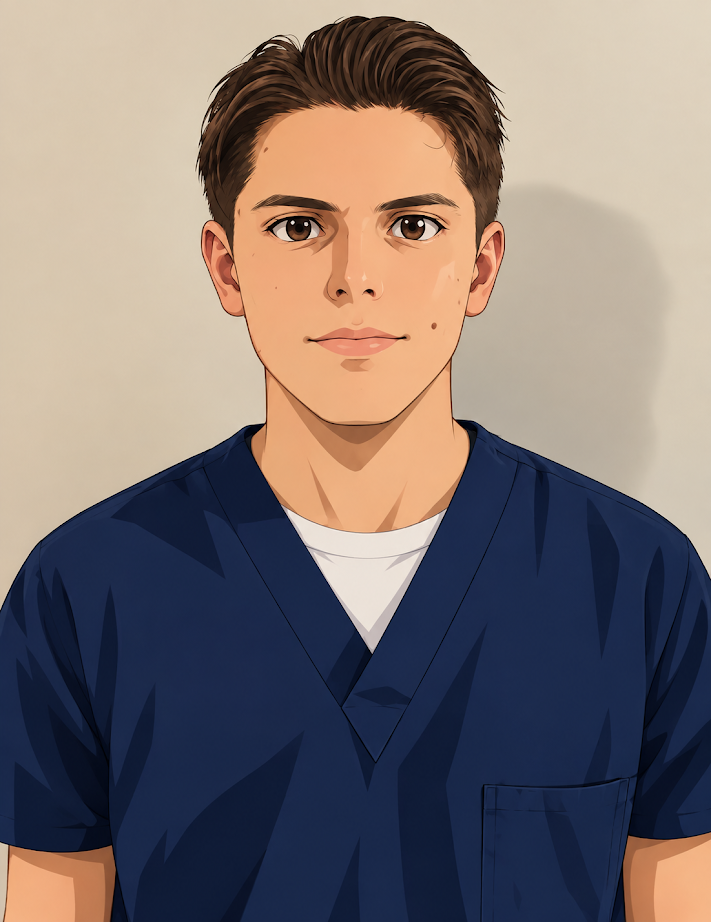

Nombre del alumno: Diego Macias Armenta

Número de control: 23212212

Correo institucional: **l23212212@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

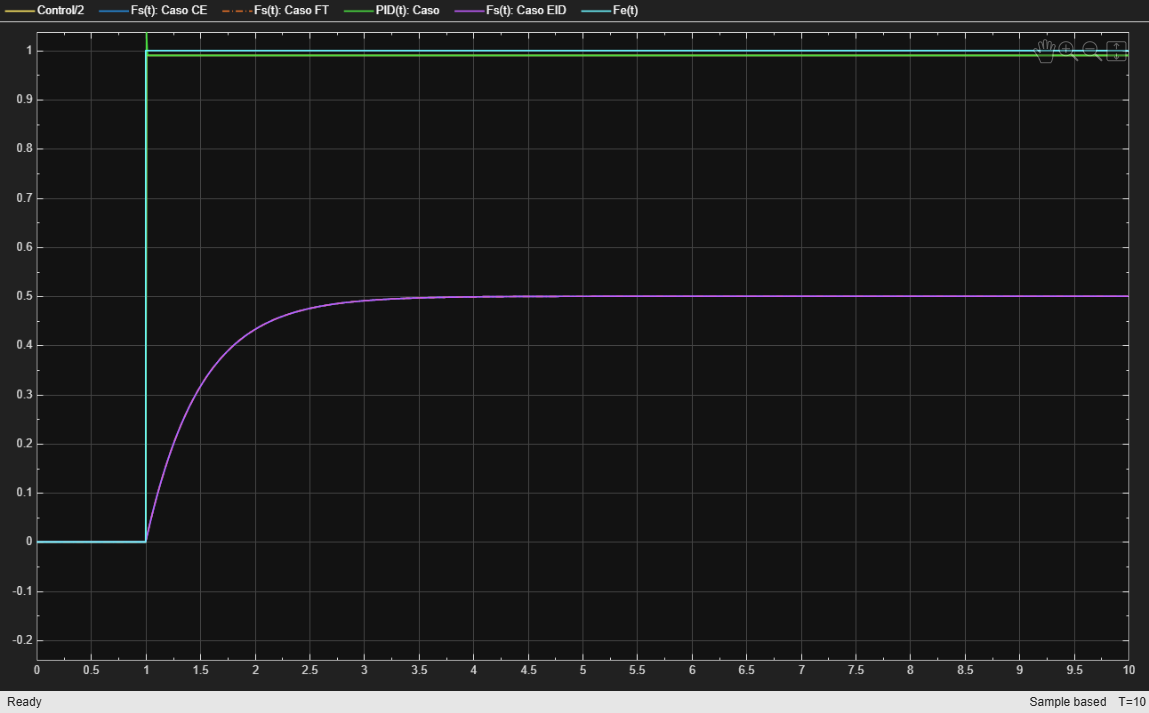

clc; clear; close all; warning('off','all')
open_system('Practica4.slx')

close_system('Practica4/Scope',0);
parameters.StopTime= '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = ' 1e-2';
x = sim('Practica4',parameters);

## Respuesta del control y el caso

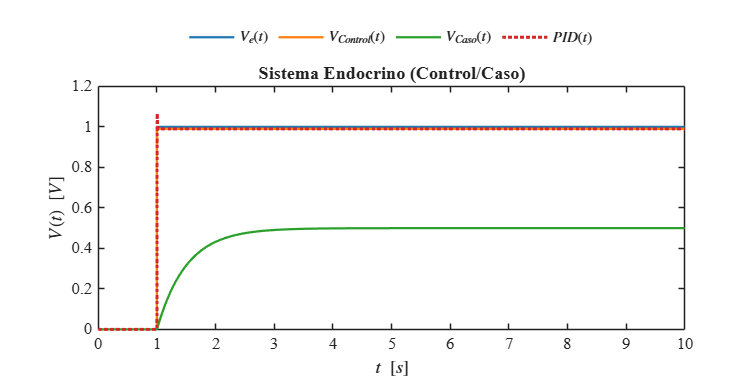

plotsignals(x.t, x.Ve, x.Control, x.Caso, x.PID, 'Sistema Endocrino (Control/Caso)')

## Función: Respuestas de la simulación

function plotsignals(t, Ve, Control, Caso, PID, nombre)
    set(figure(),'color','w')
    set(gcf,'units','inches','position',[1,1,7,3.5])
    set(gca,'fontname','times new roman','fontsize',11)
    hold on; grid off;box on;
    clr1 = [31, 119, 180]/255;
    clr2 = [255, 127, 14]/255;
    clr3 = [44, 160, 44]/255;
    clr4 = [214, 39, 40]/255;
    order = [clr1; clr2; clr3;clr4];
    colororder(order)
    P = plot(t, Ve, '-', t, Control, '-', t, Caso, '-', t, PID, ':', 'LineWidth', 1.5);
    set(P(4), 'LineWidth', 2)
    L = legend('$V_e(t)$', '$V_{Control}(t)$', '$V_{Caso}(t)$', '$PID(t)$');
    set(L, 'Interpreter', 'Latex', 'FontSize', 10, 'Location', 'NorthOutside', 'Box', 'Off', 'Orientation', 'Horizontal');
    xlabel('$t\ [s]$', 'Interpreter', 'Latex', 'FontSize', 11)
    ylabel('$V(t)\ [V]$', 'Interpreter', 'Latex', 'FontSize', 11)
    xlim([0, 10]);
    xticks(0:1:10);
    title(nombre)
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 11)
    exportgraphics(gcf, 'Sistema Endocrino Matlab.pdf', 'ContentType', 'vector')
end
